# parpool Introduction Solution

The purpose of this excercise is to learn what is a parallel pool and the different ways to use it in MATLAB.  To get started, run the following command:

doc parpool

## Open and close a parallel pool interactively

*Hint*: Look at the bottom left corner of the MATLAB desktop.

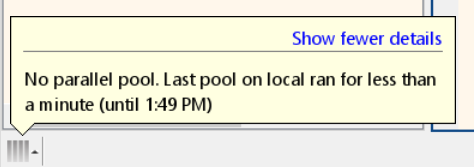

## Open and close a parallel pool programmatically

Open a parallel pool of 2 local workers through the command line.

p = parpool(2)

What happens if you try to run the above command twice?  You can't run multiple parallel pools at the same time.

## Query the number of workers in the parallel pool

p.NumWorkers

gcp will "get current pool" and return a handle to it.  If a pool has not already been started, it will create a new one first and then return the handle to it.

p = gcp

## Shutdown the parallel pool

delete(p)

Will check to see if a pool is open and if so, deletes it.

delete(gcp('nocreate'))

Will delete a pool if it exists, but won't create one first if it doesn't already exist.

*Copyright 2020 The MathWorks, Inc.*